interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

## Part e)

A = [0 0 1 0; 0 0 0 1; 0 1 0 0; 1 0 0 0];
x0 = [1 -1 0 0]';
out = sim('problem2model');
[v,d] = eig(A)

v =   -0.5000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.5000i  -0.5000 + 0.0000i
  -0.5000 + 0.0000i  -0.0000 + 0.5000i  -0.0000 - 0.5000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 - 0.0000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i


d =   -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


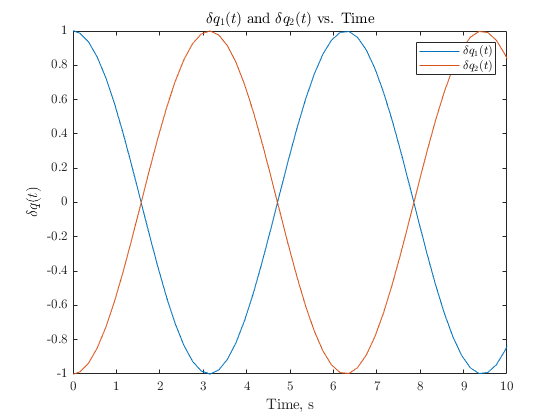

t = out.x.Time;
q1 = out.x.Data(:,1);
q2 = out.x.Data(:,2);
figure
plot(t,q1)
title('$\delta q_{1}(t)$ and $\delta q_{2}(t)$ vs. Time')
xlabel('Time, s')
ylabel('$\delta q(t)$')
hold on
plot(t,q2)
legend('$\delta q_{1}(t)$','$\delta q_{2}(t)$')
hold off

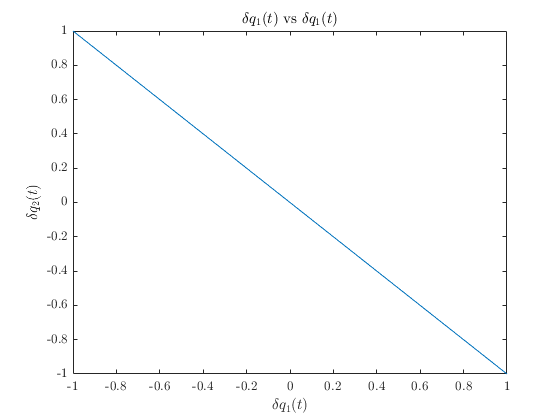

figure
plot(q1,q2)
title('$\delta q_{1}(t)$ vs $\delta q_{1}(t)$')
xlabel('$\delta q_{1}(t)$')
ylabel('$\delta q_{2}(t)$')

B = [v(:,1) v(:,2) v(:,3) v(:,4) x0];
C = rref(B);
C = C(:,end)

C =    0.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
   0.0000 + 0.0000i


xt = C(1)*exp(d(1,1)*t').*v(:,1)...
    + C(2)*exp(d(2,2)*t').*v(:,2)...
    + C(3)*exp(d(3,3)*t').*v(:,3)...
    + C(4)*exp(d(4,4)*t').*v(:,4)

xt =    1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.9995 + 0.0000i   0.9877 + 0.0000i   0.9370 + 0.0000i   0.8489 + 0.0000i   0.7269 + 0.0000i   0.5760 + 0.0000i   0.4021 + 0.0000i   0.2122 + 0.0000i   0.0139 + 0.0000i  -0.1851 + 0.0000i  -0.3766 + 0.0000i  -0.5532 + 0.0000i  -0.7076 + 0.0000i  -0.8339 + 0.0000i  -0.9269 + 0.0000i  -0.9830 + 0.0000i  -0.9999 + 0.0000i  -0.9769 + 0.0000i  -0.9150 + 0.0000i  -0.8166 + 0.0000i  -0.6856 + 0.0000i  -0.5273 + 0.0000i  -0.3480 + 0.0000i  -0.1548 + 0.0000i   0.0445 + 0.0000i   0.2421 + 0.0000i   0.4301 + 0.0000i   0.6008 + 0.0000i   0.7477 + 0.0000i   0.8647 + 0.0000i   0.9473 + 0.0000i   0.9920 + 0.0000i   0.9973 + 0.0000i   0.9628 + 0.0000i   0.8899 + 0.0000i   0.7815 + 0.0000i   0.6420 + 0.0000i   0.4768 + 0.0000i   0.2927 + 0.0000i   0.0969 + 0.0000i  -0.1028 + 0.0000i  -0.2983 + 0.0000i  -0.4820 + 0.0000i  -0.6465 + 0.0000i  -0.7852 + 0.0000i  -0.8925 + 0.0000i
  -1.0000 - 0.0000i  -1.0000 + 0.0000i  -1.0

figure
plot(t,xt(1,:))

title('$\delta q_{1}(t)$ and $\delta q_{2}(t)$ vs. Time')
xlabel('Time, s')
ylabel('$\delta q(t)$')
hold on
plot(t,xt(2,:))

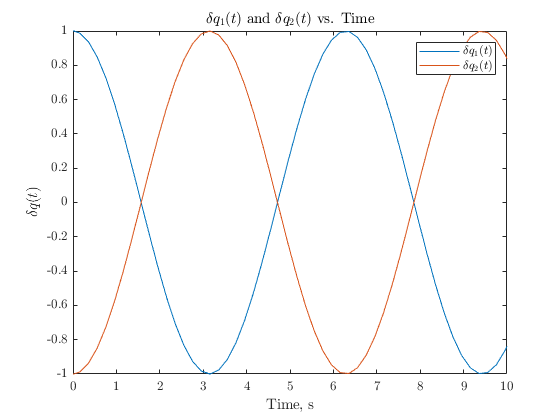

legend('$\delta q_{1}(t)$','$\delta q_{2}(t)$')
hold off

## Part f)

A = [0 0 1 0; 0 0 0 1; 0 1 0 0; 1 0 0 0]

A =      0     0     1     0
     0     0     0     1
     0     1     0     0
     1     0     0     0


x0 = [1 1 -1 -1]'

x0 =      1
     1
    -1
    -1


out = sim('problem2model');
[v,d] = eig(A)

v =   -0.5000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.5000i  -0.5000 + 0.0000i
  -0.5000 + 0.0000i  -0.0000 + 0.5000i  -0.0000 - 0.5000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 - 0.0000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i


d =   -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


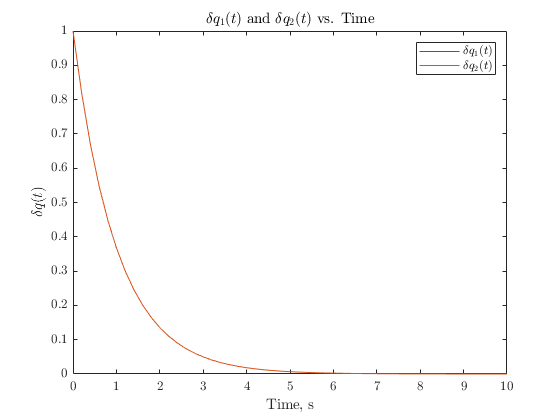

t = out.x.Time;
q1 = out.x.Data(:,1);
q2 = out.x.Data(:,2);
figure
plot(t,q1)
title('$\delta q_{1}(t)$ and $\delta q_{2}(t)$ vs. Time')
xlabel('Time, s')
ylabel('$\delta q(t)$')
hold on
plot(t,q2)
legend('$\delta q_{1}(t)$','$\delta q_{2}(t)$')
hold off

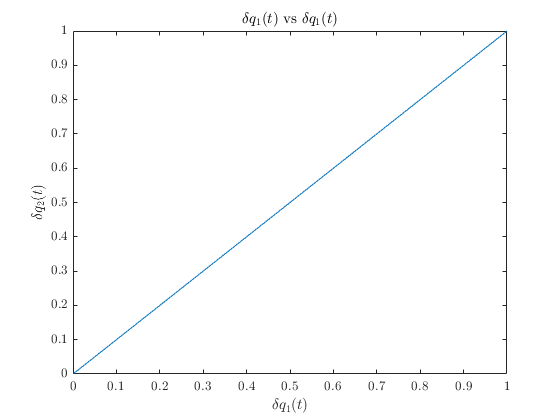

figure
plot(q1,q2)
title('$\delta q_{1}(t)$ vs $\delta q_{1}(t)$')
xlabel('$\delta q_{1}(t)$')
ylabel('$\delta q_{2}(t)$')

B = [v(:,1) v(:,2) v(:,3) v(:,4) x0];
C = rref(B);
C = C(:,end)

C =   -2.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


xt = C(1)*exp(d(1,1)*t').*v(:,1)...
    + C(2)*exp(d(2,2)*t').*v(:,2)...
    + C(3)*exp(d(3,3)*t').*v(:,3)...
    + C(4)*exp(d(4,4)*t').*v(:,4)

xt =    1.0000 - 0.0000i   0.8187 - 0.0000i   0.6703 - 0.0000i   0.5488 - 0.0000i   0.4493 - 0.0000i   0.3679 - 0.0000i   0.3012 - 0.0000i   0.2466 - 0.0000i   0.2019 - 0.0000i   0.1653 - 0.0000i   0.1353 - 0.0000i   0.1108 - 0.0000i   0.0907 - 0.0000i   0.0743 - 0.0000i   0.0608 - 0.0000i   0.0498 - 0.0000i   0.0408 + 0.0000i   0.0334 + 0.0000i   0.0273 + 0.0000i   0.0224 + 0.0000i   0.0183 + 0.0000i   0.0150 + 0.0000i   0.0123 + 0.0000i   0.0101 + 0.0000i   0.0082 + 0.0000i   0.0067 - 0.0000i   0.0055 + 0.0000i   0.0045 + 0.0000i   0.0037 + 0.0000i   0.0030 - 0.0000i   0.0025 - 0.0000i   0.0020 - 0.0000i   0.0017 - 0.0000i   0.0014 - 0.0000i   0.0011 - 0.0000i   0.0009 - 0.0000i   0.0007 - 0.0000i   0.0006 - 0.0000i   0.0005 - 0.0000i   0.0004 - 0.0000i   0.0003 - 0.0000i   0.0003 - 0.0000i   0.0002 - 0.0000i   0.0002 - 0.0000i   0.0002 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 + 0.0000i
   1.0000 - 0.0000i   0.8187 + 0.0000i   0.6

figure
plot(t,xt(1,:))

title('$\delta q_{1}(t)$ and $\delta q_{2}(t)$ vs. Time')
xlabel('Time, s')
ylabel('$\delta q(t)$')
hold on
plot(t,xt(2,:))

legend('$\delta q_{1}(t)$','$\delta q_{2}(t)$')
hold off

## Part g)

A = [0 0 1 0; 0 0 0 1; 0 1 0 0; 1 0 0 0]

A =      0     0     1     0
     0     0     0     1
     0     1     0     0
     1     0     0     0


x0 = [1 1 1 1]'

x0 =      1
     1
     1
     1


out = sim('problem2model');
[v,d] = eig(A)

v =   -0.5000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.5000i  -0.5000 + 0.0000i
  -0.5000 + 0.0000i  -0.0000 + 0.5000i  -0.0000 - 0.5000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 - 0.0000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i


d =   -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


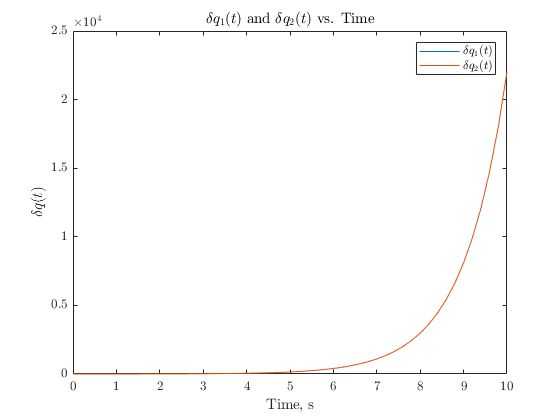

t = out.x.Time;
q1 = out.x.Data(:,1);
q2 = out.x.Data(:,2);
figure
plot(t,q1)
title('$\delta q_{1}(t)$ and $\delta q_{2}(t)$ vs. Time')
xlabel('Time, s')
ylabel('$\delta q(t)$')
hold on
plot(t,q2)
legend('$\delta q_{1}(t)$','$\delta q_{2}(t)$')
hold off

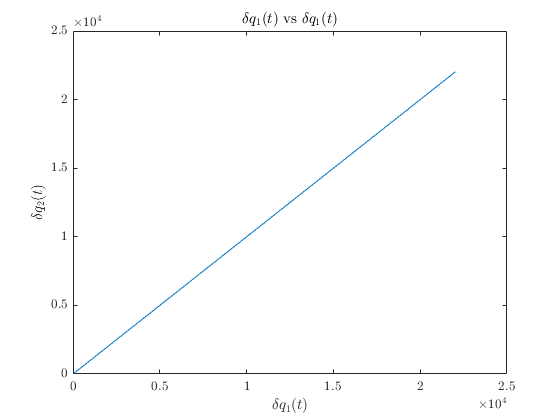

figure
plot(q1,q2)
title('$\delta q_{1}(t)$ vs $\delta q_{1}(t)$')
xlabel('$\delta q_{1}(t)$')
ylabel('$\delta q_{2}(t)$')

B = [v(:,1) v(:,2) v(:,3) v(:,4) x0];
C = rref(B);
C = C(:,end)

C =    0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -2.0000 + 0.0000i


xt = C(1)*exp(d(1,1)*t').*v(:,1)...
    + C(2)*exp(d(2,2)*t').*v(:,2)...
    + C(3)*exp(d(3,3)*t').*v(:,3)...
    + C(4)*exp(d(4,4)*t').*v(:,4)

xt = 	1.0e+04 *

   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0002 - 0.0000i   0.0002 - 0.0000i   0.0003 - 0.0000i   0.0003 - 0.0000i   0.0004 - 0.0000i   0.0005 - 0.0000i   0.0006 - 0.0000i   0.0007 - 0.0000i   0.0009 - 0.0000i   0.0011 - 0.0000i   0.0013 - 0.0000i   0.0016 - 0.0000i   0.0020 - 0.0000i   0.0025 - 0.0000i   0.0030 - 0.0000i   0.0037 - 0.0000i   0.0045 - 0.0000i   0.0055 - 0.0000i   0.0067 - 0.0000i   0.0081 - 0.0000i   0.0099 - 0.0000i   0.0122 - 0.0000i   0.0148 - 0.0000i   0.0181 - 0.0000i   0.0221 - 0.0000i   0.0270 - 0.0000i   0.0330 - 0.0000i   0.0403 - 0.0000i   0.0493 - 0.0000i   0.0602 - 0.0000i   0.0735 - 0.0000i   0.0898 - 0.0000i   0.1097 - 0.0000i   0.1339 - 0.0000i   0.1636 - 0.0000i   0.1998 - 0.0000i   0.2441 - 0.0000i   0.2981 - 0.0000i   0.3641 - 0.0000i   0.4447 - 0.0000i   0.5432 - 0.0000i   0.6634 - 0.0000i   0.8103 - 0.0000i   0.9897 - 0.0000i   1.2088 - 0.0000i   1.4765 - 0.0000i   1.8034 - 0.0000i
   0.0001 - 0.0000i   0.0001 + 0

figure
plot(t,xt(1,:))

title('$\delta q_{1}(t)$ and $\delta q_{2}(t)$ vs. Time')
xlabel('Time, s')
ylabel('$\delta q(t)$')
hold on
plot(t,xt(2,:))

legend('$\delta q_{1}(t)$','$\delta q_{2}(t)$')
hold off